9.45

close all
clear
clc

mot.k = 5.2;
mot.T = 0.03;
Td = 0.01;
Ts = 0.002;
N = 5;

s = tf('s');
Pmc = mot.k  / (s * (mot.T * s + 1));
Pmd = c2d(Pmc, Ts, "zoh");
z = tf('z', Ts);
Pd = z^-N;

P = minreal(Pmd * Pd, 1e-6);

pid.Kp = 15;
pid.Ki = 280;
pid.Kd = 0.21;

Cc = pid.Kp + pid.Ki / s + pid.Kd * s;
s = (z - 1) / Ts;
CdBE = minreal(pid.Kp + pid.Ki / s + pid.Kd * s, 1e-6);
s = (1 - z^-1) / Ts;
CdFE = minreal(pid.Kp + pid.Ki / s + pid.Kd * s, 1e-6);
CdTU = c2d(Cc, Ts, "tustin");

close all
figure(1)
hold on
bode(Cc, "r")
bode(CdBE, "g")
bode(CdFE, "b")
bode(CdTU, "k")
legend("Tempo continuo", "BE", "FE", "TU")
title("Confronto tra i diagrammi di Bode")

La risposta in fase è approssimata meglio dalla discretizzazione tramite Tustin.

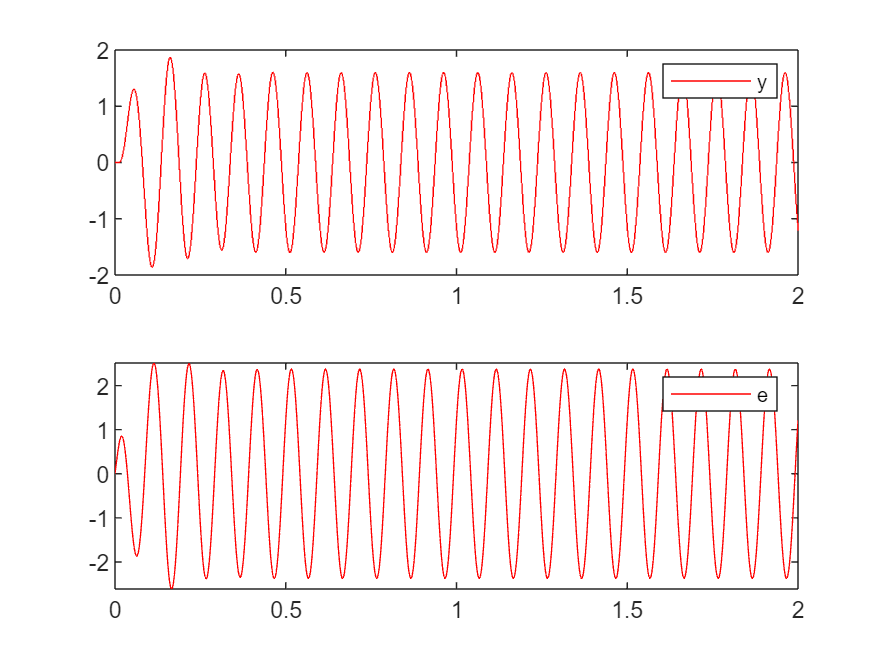

T1 = minreal(feedback(CdTU * P, 1), 1e-6);
w = 2 * pi * 10;
t = 0:Ts:2;
sint = sin(w * t);
y = lsim(T1, sint, t).';
e = sint - y;
close all
figure(2)
subplot(2, 1, 1)
stairs(t, y, "r")
legend("y")
subplot(2, 1, 2)
plot(t, e, "r")
legend("e")

s = (1 - z^-1) / Ts;
F1 = minreal(mot.T / mot.k * s^2 + s / mot.k, 1e-6);
F = minreal(z^N * F1, 1e-6);

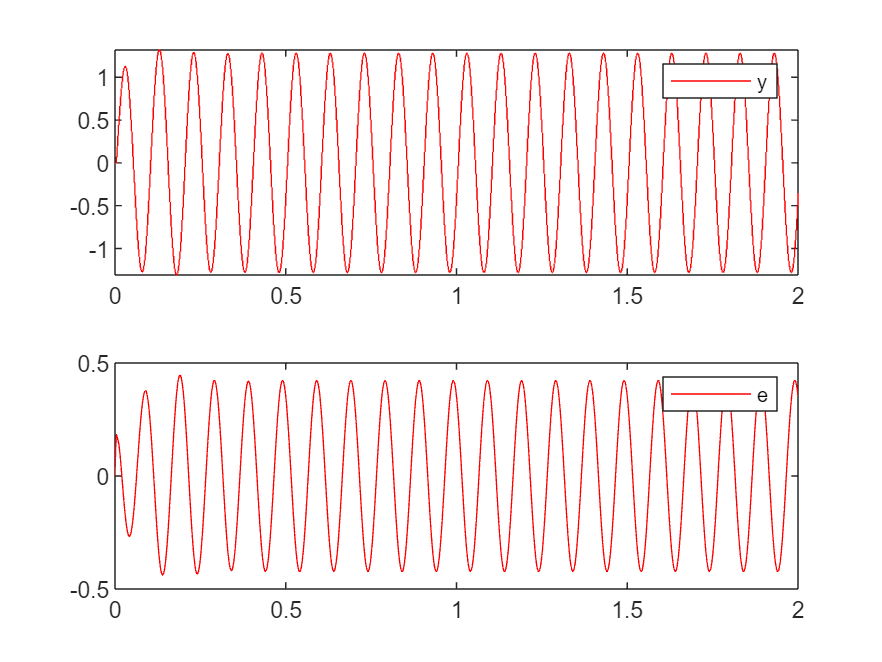

T2 = minreal(P * (CdTU + F) / (1 + P * CdTU), 1e-6);
y1 = lsim(T2, sint, t).';
e1 = sint - y1;
close all
figure(3)
subplot(2, 1, 1)
stairs(t, y1, "r")
legend("y")
subplot(2, 1, 2)
plot(t, e1, "r")
legend("e")

10.04